%we have 60 intervals of time 
round = 60;
%initial value of input
u_2_2_1 = 30*ones(1,61);
u_2_2_2 = 45*ones(1,61);
%for annealing, we define tempreture and iteration times
temperature = 100;      
stop_temperature = 0.0001;
%because we swtich the order of input randomly, we should run multiple
%times for one input, here a iteration number is defined.
iter = 20;               
count = 0;
golden_iter = 3;

TTS_previous_2_2_1 = TTS_calculate(u_2_2_1(1,1), u_2_2_1(1,2:61));
[u_optimal_2_2_1, TTS_current_2_2_1,TTS_history_2_2_1] =...
    goldensection(u_2_2_1,TTS_previous_2_2_1,golden_iter);
TTS_current_2_2_1

TTS_current_2_2_1 = 7.7815e+05

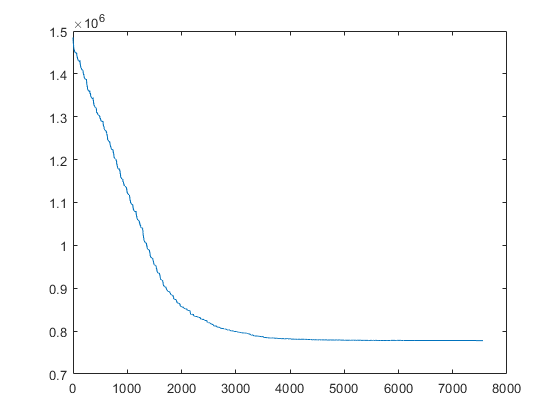



[minTTS_2_2_1,u_final_2_2_1,count_2_2_1,temp_TTS_history_2_2_1] = ...
    annealing_multi(u_optimal_2_2_1,temperature,stop_temperature,round,count,iter);
TTS_history_2_2_1=[TTS_history_2_2_1,temp_TTS_history_2_2_1];
plot(TTS_history_2_2_1)


disp("The optimal TTS from initial point 15s:" );

The optimal TTS from initial point 15s:


disp("TTS(from 15)=");

TTS(from 15)=


disp(minTTS_2_2_1);

   7.7793e+05



disp("Corresponding U=")

Corresponding U=


disp(u_final_2_2_1);

  列 1 至 6

   27.3520   21.4533   26.3824   26.0075   25.4845   24.1866

  列 7 至 12

   29.5628   26.9735   27.9081   25.2987   23.9238   24.5402

  列 13 至 18

   28.1437   23.7057   28.1863   29.0308   28.3736   25.1899

  列 19 至 24

   23.9848   29.1383   24.7660   25.4014   28.3192   28.1887

  列 25 至 30

   29.9955   29.3336   28.8008   28.1076   34.8994   29.8555

  列 31 至 36

   33.8421   34.5821   33.8148   28.8250   29.3266   22.3725

  列 37 至 42

   23.3481   27.0509   23.1909   22.3468   26.6753   32.0603

  列 43 至 48

   28.7175   26.0329   28.3404   24.5028   34.2889   26.8002

  列 49 至 54

   34.2813   31.9140   33.9021   34.9154   36.1113   35.4757

  列 55 至 60

   35.8934   35.3506   35.8130   35.3461   35.9072   35.9327

  列 61

   18.5241





TTS_previous_2_2_2 = TTS_calculate(u_2_2_2(1,1), u_2_2_2(1,2:61));
[u_optimal_2_2_2, TTS_current_2_2_2,TTS_history_2_2_2] =...
    goldensection(u_2_2_2,TTS_previous_2_2_2,golden_iter);


[minTTS_2_2_2,u_final_2_2_2,count_2_2_2,temp_TTS_history_2_2_2] = ...
    annealing_multi(u_optimal_2_2_2,temperature,stop_temperature,round,count,iter);
TTS_history_2_2_2=[TTS_history_2_2_2,temp_TTS_history_2_2_2]

TTS_history_2_2_2 = 	1.0e+06 *

    1.7399    1.7412    1.7420    1.7379    1.7375    1.7368    1.7381    1.7372    1.7367    1.7367    1.7390    1.7377    1.7389    1.7356    1.7349    1.7366    1.7356    1.7347    1.7363    1.7349    1.7341    1.7325    1.7333    1.7325    1.7309    1.7319    1.7312    1.7315    1.7297    1.7299    1.7287    1.7274    1.7281    1.7276    1.7268    1.7272    1.7273    1.7262    1.7261    1.7256    1.7256    1.7257    1.7254    1.7252    1.7253    1.7249    1.7249    1.7252    1.7252    1.7244


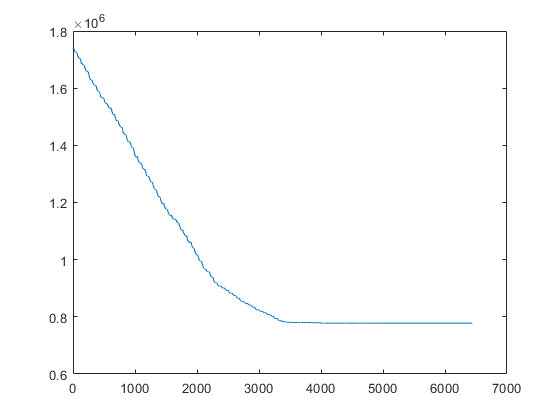

plot(TTS_history_2_2_2)


disp("The optimal TTS from initial point 45s:" );

The optimal TTS from initial point 45s:


disp("TTS(from 45)=");

TTS(from 45)=


disp(minTTS_2_2_2);

   7.7792e+05



disp("Corresponding U=");

Corresponding U=


disp(u_final_2_2_2);

  列 1 至 6

   35.2069   29.5186   28.9769   26.6303   27.3237   29.0149

  列 7 至 12

   29.3253   25.9702   23.9352   23.6574   30.1548   29.6736

  列 13 至 18

   24.8467   29.8189   27.1359   25.7962   24.2482   25.3232

  列 19 至 24

   25.6296   24.7275   30.0231   25.6251   29.3026   28.7293

  列 25 至 30

   29.7062   29.1068   30.7939   29.1053   31.4740   34.9691

  列 31 至 36

   29.8043   35.8947   32.3538   31.1936   25.8785   27.6193

  列 37 至 42

   34.5637   28.3956   26.1574   30.4546   23.1711   34.9761

  列 43 至 48

   35.1548   33.3954   35.1465   29.1865   33.4689   34.1955

  列 49 至 54

   35.5221   32.4493   33.2631   35.8780   36.0202   35.5932

  列 55 至 60

   35.9049   35.8541   35.8678   35.8993   35.7755   35.8561

  列 61

   43.5273



function u_new = turbulent(u_old,n)
    p1 = floor(1+n*rand());
    p2 = floor(1+n*rand());
    
    while p1==p2
        p1 = floor(1+n*rand());
        p2 = floor(1+n*rand());    
    end
    
    tmp = u_old(p1);
    u_old(p1) = u_old(p2)+2*rand()-1;
    u_old(p2) = tmp+2*rand()-1;    
    
    u_new = u_old;
end

%when we obtain a new solution by slighty randomly swtich the order of
%previous solution, we can compute new TTS by following function
function [u1,TTS] = TTS_campare(TTS,TTS1,TTS2,temperature,u1,u2)
    %TTS1 is the old solution.
    delta_TTS = TTS2-TTS1;
    if delta_TTS < 0
        u1 = u2;
        TTS = [TTS TTS2];
    else
            if exp(-delta_TTS/temperature)>rand() 
                u1 = u2;  
                TTS = [TTS TTS2];
            end
        TTS = [TTS TTS1];
    end    
end

%we can try different inputs to check whether the result we got is the
%loacol optimization or not.
function [TTS_optimal,count,u1,TTS_history] = annealing(u0,temperature,stop_temperature,round)
    count = 1;
    u1 = u0;
    TTS_history = [];
    while temperature > stop_temperature

        TTS1 = TTS_calculate(u1(1,1),u1(1,2:60));
        u2 = turbulent(u1,round);
        TTS2 = TTS_calculate(u2(1,1),u2(1,2:60));

        [u1,TTS_history] = TTS_campare(TTS_history,TTS1,TTS2,temperature,u1,u2);

        count = count + 1;
        if rem(count,10) == 0
            temperature = temperature*0.9;        
        end    
    end
    TTS_optimal = TTS_history(end);   
    if nargout==1
        TTS_optimal;
    end
end

%we can run annealing multiple times to eliminate the influence of
%random solution selection
function [TTS_final,u_final,count,TTS_history] = annealing_multi(u0,temperature,stop_temperature,round,count,iter)

    [TTS_final,count,u_final,TTS_history] = annealing(u0,temperature,stop_temperature,round);  
    for i = 1:1:iter
        [final_TTS_u0_1,temp_count,temp_u,temp_TTS_history] = annealing(u0,temperature,stop_temperature,round);
        count = count + temp_count;
        if final_TTS_u0_1<TTS_final
           TTS_final = final_TTS_u0_1; 
           TTS_history=temp_TTS_history;
           u_final = temp_u;
        end
    end
end

%%for golden section method


%golden section is to calculate the local minimum within a given interval, the output can be modified input can corresponding TTS.
function [unew, TTS_current] = golden_section_once(k,u0)

    step = 2*rand()-1;    
    while ((u0(k) + step) >= 45) && ((u0(k) + step) <= 15)
        step = 2*rand()-1;        
    end
  
    lb = u0(k);
    ub = u0(k) + step;
    
    tol = 1.0e-6;
    % if nargin < 4; tol = 1.0e-6; end
    
    nIter = ceil(-2.078087*log(tol/abs(lb-ub)));
    golden1 = 0.618033989;
    golden2 = 1 - golden1;
    % First telescoping
    x1 = golden1*ub + golden2*lb;
    x2 = golden2*ub + golden1*lb;
    
    u_1 = u0; u_1(1,k) = x1;
    u_2 = u0; u_2(1,k) = x2;
    u_lb = u0;u_lb(1,k) = lb;
    u_ub = u0;u_ub(1,k) = ub;
    
    f1 = TTS_calculate(u_1(1,1), u_1(1,2:61));
    f2 = TTS_calculate(u_2(1,1), u_1(1,2:61));
    flb = TTS_calculate(u_lb(1,1), u_lb(1,2:61));
    fub = TTS_calculate(u_ub(1,1), u_ub(1,2:61));
    
    % 
    for i =1:1:nIter
        if f1 > f2
            lb = x1; x1 = x2; f1 = f2;
            x2 = golden2*lb + golden1*ub;
            u_2(1,k) = x2;
            f2 = TTS_calculate(u_2(1,1), u_1(1,2:61));
            unew = u_2;
            TTS_current = f2;
        elseif f1<f2
            ub = x2; x2 = x1; f2 = f1;
            x1 = golden1*lb + golden2*ub;
            u_1(1,k) = x1;
            f1 = TTS_calculate(u_2(1,1), u_1(1,2:61));
            unew = u_1;
            TTS_current = f1;
        else
            unew = u_ub;
            TTS_current = fub;
        end
    end    
end


%we must be carfeul when dealing with this function's stop certerion, we should count how many times we observe the same output
%when the number is large enough, we stop the searching. 
%haven't finished yet
function [u_output,TTS_current,TTS_optimal_history] = goldensection(u_input,TTS_previous0,golden_iter)
    count_number = 0;
    TTS_previous = TTS_previous0;
    TTS_previous_round = TTS_previous;
    TTS_optimal_history=[];
    while count_number < golden_iter
        for i = 1:1:61
            [u_output, TTS_current] = golden_section_once(i,u_input);
            if(TTS_current > TTS_previous)
            else
                u_input = u_output;
                TTS_previous = TTS_current;
            end 
            TTS_optimal_history=[TTS_optimal_history,TTS_current];
        end
        if TTS_current == TTS_previous_round
            count_number = count_number + 1;
        end
        TTS_previous_round = TTS_current;
    end
end